# Question 8.6 Solution

clear all
close all

Recall from Workshop 6 that we used numerous interpolation techniques to interpolate the temperature data measured in a lake

zdata=[0.0 2.3 4.9 9.1 13.7 18.3 22.9 27.2];
tdata=[22.8 22.8 22.8 20.6 13.9 11.7 11.1 11.1];

As a reminder, we found that the cubic spline performed the best compared with the other imterpolation techniques, which may be seen below.

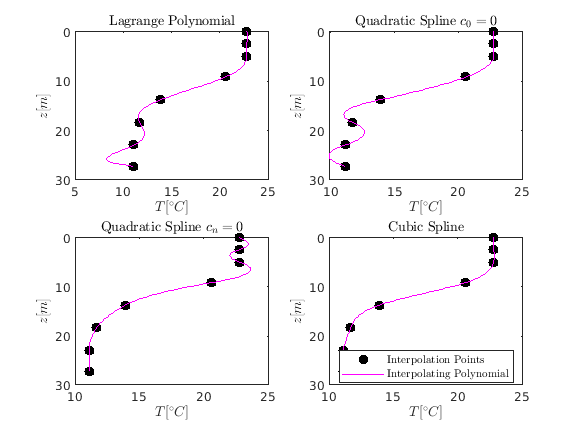

z = linspace(zdata(1),zdata(end),100);
n = length(zdata)-1; 
t_lagrange = LagrangePolynomial(zdata,tdata,n,z);
[a0,b0,c0]=QuadraticSplineCoeffsC0Eq0(zdata,tdata);
t_quadsplinec0 = QuadraticSplineEval(a0,b0,c0,zdata,z);
[an,bn,cn] = QuadraticSplineCoeffsCnEq0(zdata,tdata);
t_quadsplinecn = QuadraticSplineEval(an,bn,cn,zdata,z);
t_cubicspline = interp1(zdata,tdata,z,'spline');

subplot(2,2,1)
plot(tdata,zdata,'k.','MarkerSize',25)
hold on
plot(t_lagrange,z,'m-')
xlabel('$T [^{\circ}C]$','interpreter','latex')
ylabel('$z [m]$','interpreter','latex')
set ( gca, 'ydir', 'reverse' )
title('Lagrange Polynomial','interpreter','latex')
subplot(2,2,2)
plot(tdata,zdata,'k.','MarkerSize',25)
hold on
plot(t_quadsplinec0,z,'m-')
xlabel('$T [^{\circ}C]$','interpreter','latex')
ylabel('$z [m]$','interpreter','latex')
set ( gca, 'ydir', 'reverse' )
title('Quadratic Spline $c_{0}=0$','interpreter','latex')
subplot(2,2,3)
plot(tdata,zdata,'k.','MarkerSize',25)
hold on
plot(t_quadsplinecn,z,'m-')
xlabel('$T [^{\circ}C]$','interpreter','latex')
ylabel('$z [m]$','interpreter','latex')
set ( gca, 'ydir', 'reverse' )
title('Quadratic Spline $c_{n}=0$','interpreter','latex')
subplot(2,2,4)
plot(tdata,zdata,'k.','MarkerSize',25)
hold on
plot(t_cubicspline,z,'m-')
xlabel('$T [^{\circ}C]$','interpreter','latex')
ylabel('$z [m]$','interpreter','latex')
set ( gca, 'ydir', 'reverse' )
title('Cubic Spline','interpreter','latex')
legend('Interpolation Points','Interpolating Polynomial','location','best','interpreter','latex')

To estimate the position of the thermocline, we can then take the second derivative of the cubic spline curve using a central difference method. In this case, we'll consider using 101 points.

N = 100;

N = 100

z = linspace(zdata(1),zdata(end),N+1);
T = interp1(zdata,tdata,z,'spline');
D2T = zeros(size(z));

For the interior nodes $i=1,\ldots,N-1$ (or in terms of MATLAB's indexing $\texttt{index=2,...,N}$, we may apply central difference formula to give


$$\Big(\frac{d^{2}T}{dz^{2}}\Big)_{i}=\frac{T_{i-1}-2T_{i}+T_{i+1}}{\Delta^{2}}$$


delta = z(2)-z(1);
D2T(2:N) = (T(1:N-1)-2*T(2:N)+T(3:N+1))/(delta^2);

For the point $i=0$, we have to use a forward difference method, giving


$$\Big(\frac{d^{2}T}{dz^{2}}\Big)_{0}=\frac{T_{2}-2T_{1}+T_{0}}{\Delta^{2}}$$


D2T(1) = (T(3)-2*T(2)+T(1))/(delta^2);

And similarly, for the endpoint $i=N$, the backwards difference method gives


$$\Big(\frac{d^{2}T}{dz^{2}}\Big)_{N}=\frac{T_{N}-2T_{N-1}+T_{N-2}}{\Delta^{2}}$$


D2T(N+1) = (T(N+1)-2*T(N)+T(N-1))/(delta^2);

Plotting, we have

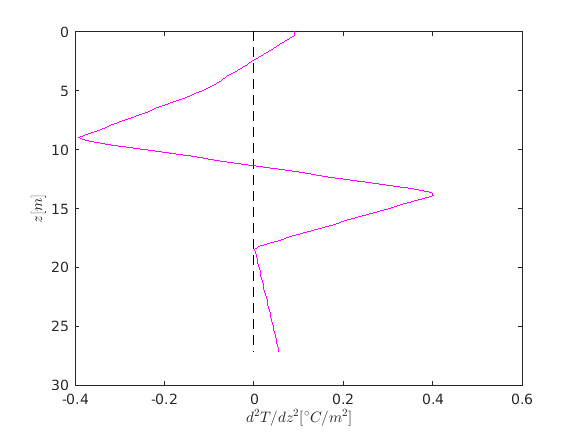

figure(101)
plot(D2T,z,'m-')
hold on
plot(zeros(size(z)),z,'k--')
hold off
xlabel('$d^{2}T/dz^{2} [^{\circ}C/m^{2}]$','interpreter','latex')
ylabel('$z [m]$','interpreter','latex')
set ( gca, 'ydir', 'reverse' )

We see that there are two positions where the second derivative vanishes, at $z\approx2.5$ and $z\approx12$. However, if we recall the definition of a thermocline, its defined as the separating layer between two separate environments in a lake. Therefore, physically, the point $z\approx2.5$ can't represent a thermocline. If we look at the behaviour of the cubic spline for $z<5$

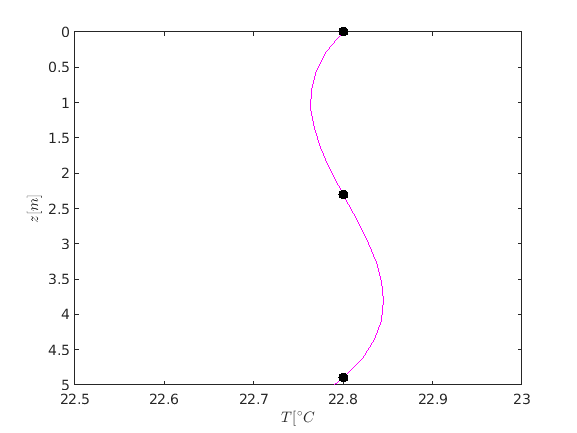

figure(102)
plot(T,z,'m-')
hold on
plot(tdata,zdata,'k.','MarkerSize',25)
hold off
xlabel('$T [^{\circ}C]$','interpreter','latex')
ylabel('$z [m]$','interpreter','latex')
xlim([22.5,23])
ylim([0,5])
set ( gca, 'ydir', 'reverse' )

there is a slight oscillation in the spline causing an inflection point at the second data point, which causes the erroneous result.

function fi=QuadraticSplineEval(a,b,c,xdata,xi)
n=length(xdata)-1;
fi=zeros(1,length(xi));
for i=1:length(xi) 
    for j=1:n
        if xdata(j)>xi(i)
            j=j-1;
        break
        end
    end
    fi(i)=a(j)+b(j)*(xi(i)-xdata(j))+c(j)*(xi(i)-xdata(j))^2;
end
end

function [a,b,c]=QuadraticSplineCoeffsC0Eq0(xdata,fdata)
n=length(xdata)-1;     %/* number of intervals */
a=zeros(1,n+1);
b=zeros(1,n+1);
c=zeros(1,n+1);
for i=1:n+1
    a(i)=fdata(i);
end

c(1) = 0.0;
h(1) = xdata(2)-xdata(1);

for i=2:n
    h(i) = xdata(i+1)-xdata(i);
    c(i) = (1/h(i))*(a(i+1)/h(i)-a(i)*((1/h(i-1))+(1/h(i)))+a(i-1)/h(i-1)-c(i-1)*h(i-1));
end

for i=1:n
    b(i)=(a(i+1)-a(i))/h(i)-c(i)*h(i);
end
end

function [a,b,c]=QuadraticSplineCoeffsCnEq0(xdata,fdata)
n=length(xdata)-1;     %/* number of intervals */
a=zeros(1,n+1);
b=zeros(1,n+1);
c=zeros(1,n+1);
for i=1:n+1
    a(i)=fdata(i);
end


h(1) = xdata(2)-xdata(1);
c(n)=0.0;
h(n)=xdata(n+1)-xdata(n);

for i=n:-1:2
    h(i-1) = xdata(i)-xdata(i-1);
    c(i-1) = ((1/h(i-1))*(a(i+1)/h(i)-a(i)*((1/h(i-1))+(1/h(i)))+a(i-1)/h(i-1)-c(i)*h(i)));
end


for i=1:n
    b(i)=(a(i+1)-a(i))/h(i)-c(i)*h(i);
end

end

function yint=LagrangePolynomial(x,y,n,xint)
yint=zeros(size(xint));
for i=1:n+1
    Lix=1.0;
    for j=1:n+1
        if j ~= i
        Lix=Lix.*(xint-x(j))/(x(i)-x(j));
        end
    end
    yint=yint+y(i).*Lix;
end
end